clear
load data3.mat
n=length(data.CzasLokalnyUTC0100)

n = 3060

data.CzasLokalnyUTC0100(1:4)

ans = 4×1 datetime array
   2024-05-20 23:00:00
   2024-05-20 23:01:00
   2024-05-20 23:02:00
   2024-05-20 23:02:00


data.CzasLokalnyUTC0100(n-3:n)

ans = 4×1 datetime array
   2024-05-23 01:57:00
   2024-05-23 01:58:00
   2024-05-23 01:59:00
   2024-05-24 02:00:00


We see data was collected for over two days. 

From time vector:

T=60; %[s]
fs=1/T; %[Hz]
t_all=T*(0:n-1);

Kompresor1=data.StanKompresor;
StanCzujnikaZamkniecia=data.StanCzujnikZamkniciaDrzwi;



TemperaturaOtoczenia=0.1*data.TemperaturaOtoczenia;
Wlot=0.1*data.TemperaturaSterujca;


X=[Kompresor1,StanCzujnikaZamkniecia,...
    TemperaturaOtoczenia,Wlot]';

t=T*(1:n);
size(X)

ans =            4        3060


[dataWithoutNans,nan_indices]  = GetRidOfNans(X);
find(nan_indices,~0)


ans =

  0×1 empty double column vector



no nans

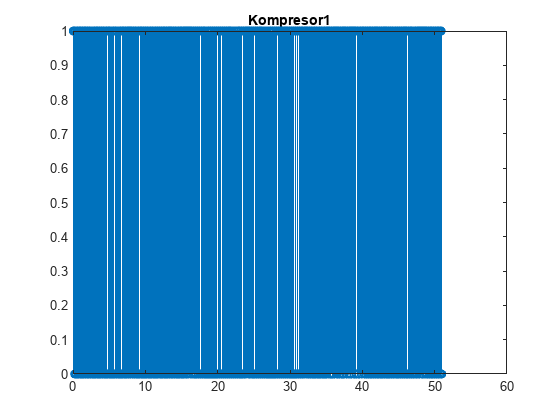

stem(t./(60*60),X(1,:))
title('Kompresor1')

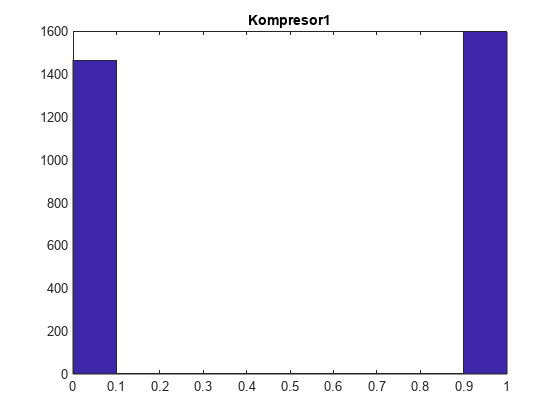

hist(X(1,:))
title('Kompresor1')

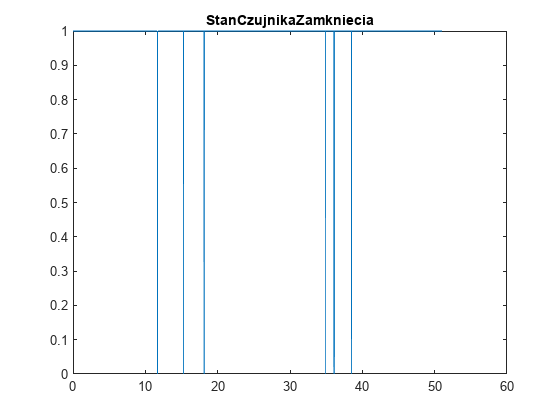

plot(t/(60*60),X(2,:))
title('StanCzujnikaZamkniecia')

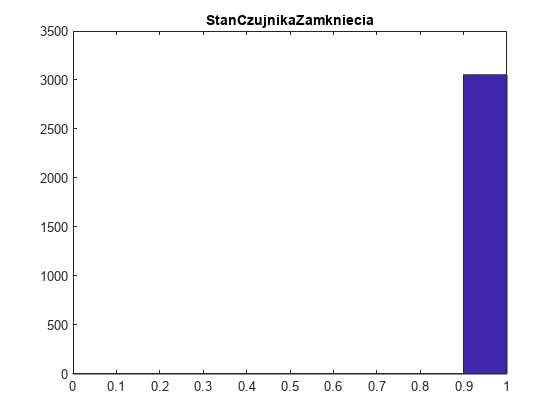

hist(X(2,:))
title('StanCzujnikaZamkniecia')

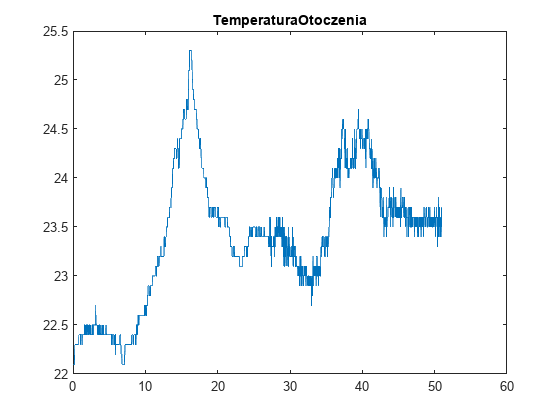

plot(t/(60*60),X(3,:))
title('TemperaturaOtoczenia')

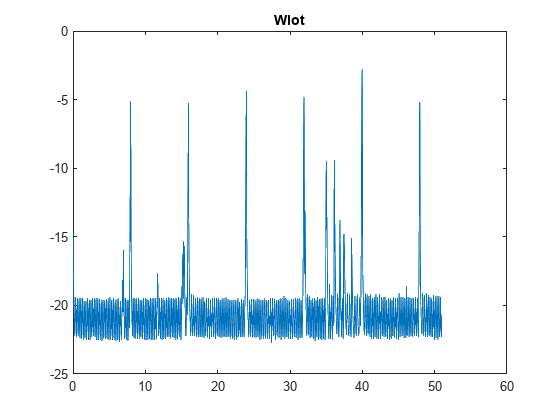

plot(t/(60*60),X(4,:))
title('Wlot')

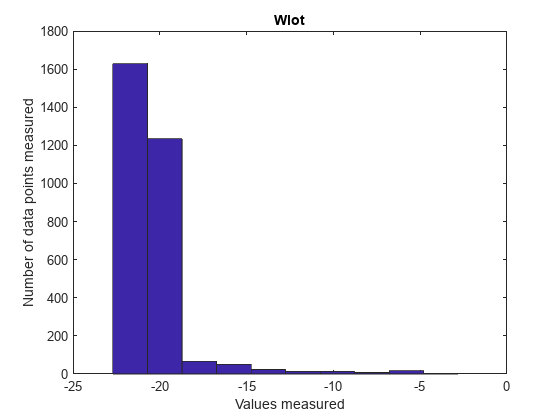

hist(X(4,:))
title('Wlot')
xlabel('Values measured')
ylabel('Number of data points measured')

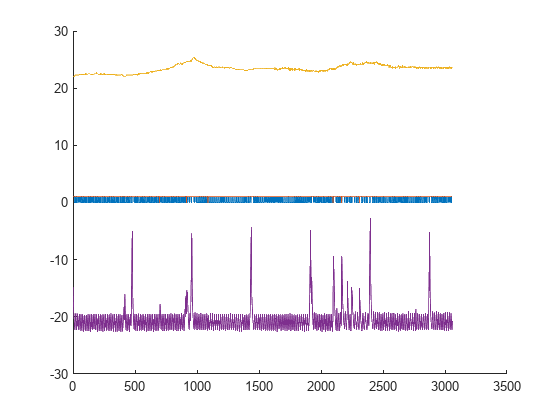

figure
hold on
plot(t/60,X)